cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc
cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

participant = participant_array(1);
ml_task_ref = participant.cond_dict("xpar").task_dict("ml");
ml_task_obj = ml_task_ref{:};
cl_task_ref = participant.cond_dict("xpar").task_dict("cl");
cl_task_obj = cl_task_ref{:};
hl_task_ref = participant.cond_dict("xpar").task_dict("hl");
hl_task_obj = hl_task_ref{:};

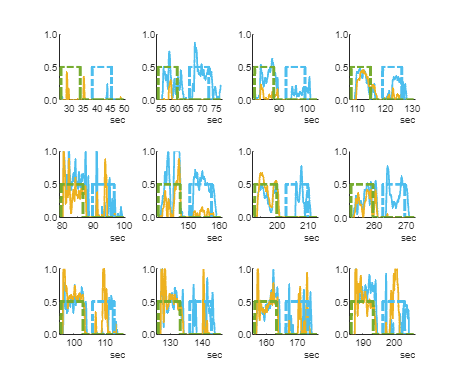

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [15, 5, 13.5, 11.25])
tiledlayout(3,4);
coact_des = {"Color", "#EDB120", "LineWidth", 1.5};
diffact_des = {"Color", "#4DBEEE", "LineWidth", 1.5};
coact_obs = {"Color", "#77AC30", "LineStyle", "-.", "LineWidth", 2.5};
diffact_obs = {"Color", "#4DBEEE", "LineStyle", "-.", "LineWidth", 2.5};

for trial_num = 1:4
trial_idxs = ml_task_obj.data_ttbl.Trial == sprintf("Trial %02d", trial_num);
kalman_name = sprintf("Kalman %02d", trial_num);
trial_ttbl = ml_task_obj.data_ttbl(trial_idxs, ["Targets", kalman_name]);
trial_ttbl = renamevars(trial_ttbl, kalman_name, "Kalman");
nexttile
hold on
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,1), diffact_des{:})
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,5), coact_des{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,1), diffact_obs{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,5), coact_obs{:})
hold off
ylim([0,1])
yticks([0, 0.5, 1])
ytickformat("%0.1f")
axis square
end
for trial_num = 1:4
trial_idxs = cl_task_obj.data_ttbl.Trial == sprintf("Trial %02d", trial_num);
trial_ttbl = cl_task_obj.data_ttbl(trial_idxs, ["Targets", "Kalman"]);
nexttile
hold on
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,1), diffact_des{:})
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,5), coact_des{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,1), diffact_obs{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,5), coact_obs{:})
hold off
ylim([0,1])
yticks([0, 0.5, 1])
ytickformat("%0.1f")
axis square
end
for trial_num = 1:4
trial_idxs = hl_task_obj.data_ttbl.Trial == sprintf("Trial %02d", trial_num);
trial_ttbl = hl_task_obj.data_ttbl(trial_idxs, ["Targets", "Kalman"]);
nexttile
hold on
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,1), diffact_des{:})
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,5), coact_des{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,1), diffact_obs{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,5), coact_obs{:})
hold off
ylim([0,1])
yticks([0, 0.5, 1])
ytickformat("%0.1f")
axis square
end

print(fig_h, '../../results/eps-figs/out-rmse', '-depsc', '-r600', '-vector')

print(fig_h2, '../../results/eps-figs/out-rmse-init', '-depsc', '-r600', '-vector')

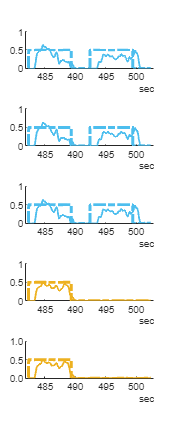

coact_des = {"Color", "#EDB120", "LineWidth", 1.5};
diffact_des = {"Color", "#4DBEEE", "LineWidth", 1.5};
coact_obs = {"Color", "#EDB120", "LineStyle", "-.", "LineWidth", 2.5};
diffact_obs = {"Color", "#4DBEEE", "LineStyle", "-.", "LineWidth", 2.5};
fig_h3 = figure;
set(fig_h3, 'Renderer', 'painters');
set(fig_h3, "Units","centimeters", "Position", [15, 5, 5, 12.5])
tiledlayout(5,1)
trial_num = 8;
trial_idxs = cl_task_obj.data_ttbl.Trial == sprintf("Trial %02d", trial_num);
trial_ttbl = cl_task_obj.data_ttbl(trial_idxs, ["Targets", "Kalman"]);
ax_list = [];
for i =1:3
ax = nexttile;
hold on
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,1), diffact_des{:})
plot(trial_ttbl.Time, trial_ttbl.Targets(:,1), diffact_obs{:})
ax_list = [ax_list, ax];
end
for i =1:2
ax = nexttile;
hold on
plot(trial_ttbl.Time, trial_ttbl.Targets(:,5), coact_obs{:})
plot(trial_ttbl.Time, trial_ttbl.("Kalman")(:,5), coact_des{:})
ax_list = [ax_list, ax];
end
hold off
ylim(ax_list, [0,1])
yticks([0, 0.5, 1])
ytickformat("%0.1f")

% axis square

print(fig_h3, '../../results/eps-figs/intro-rmse', '-depsc', '-r600', '-vector')